# Ex2

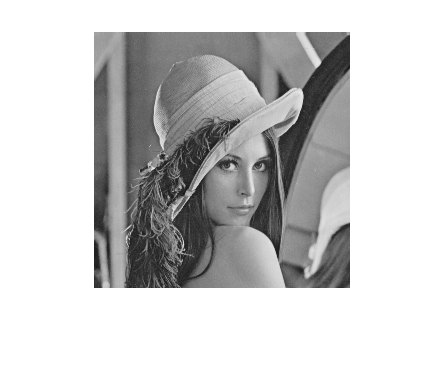


clear all;

%I : image
%L : LUT associée à l'image
[I, L] = imread("lena.tif");
%Affichage de lena sans la LUT
imshow(I);

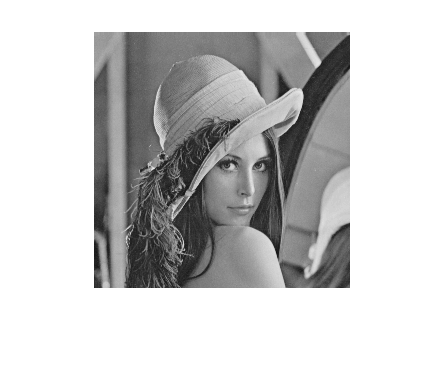

%Affiche de lena avec une LUT de 64 niveaux (Divisé par 4)
imshow(I,L);

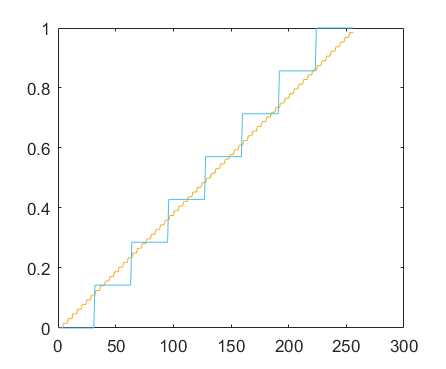

plot(L);

%requantification en 8 niveaux de gris
NewLut = recantification(8);
hold on; plot(NewLut);

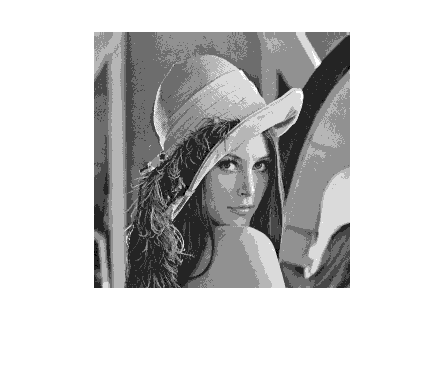

figure
imshow(I, NewLut);

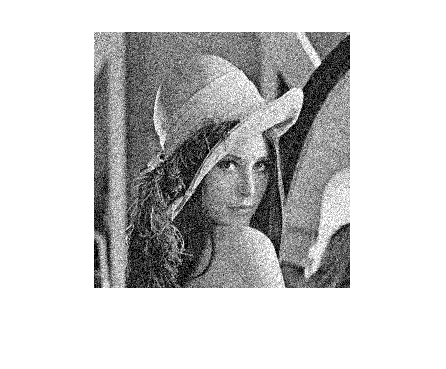


%Image bruité
Ib = imnoise(I, 'gaussian', 0, 0.01);
imshow(Ib, NewLut);

# Ex3

clear all;

### Q1

%Histo

### Q2

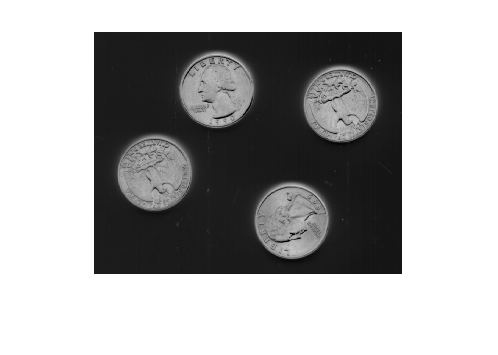

[I, L] = imread("eight.tif");
imshow(I, L);

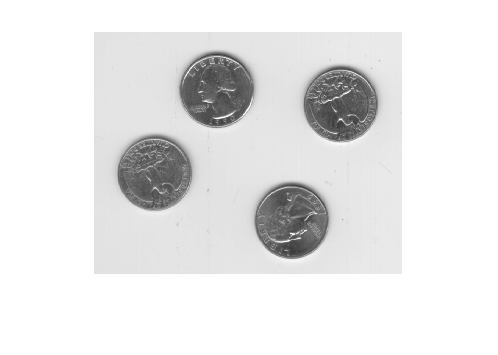

imshow(I);

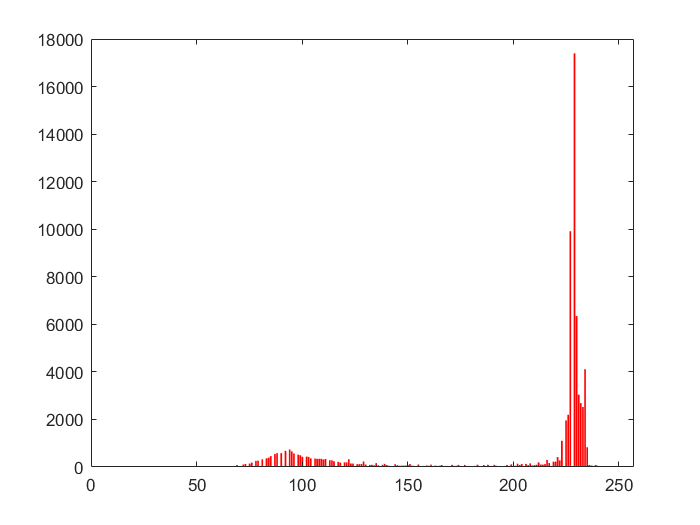

H = Histo(I);

### Q3

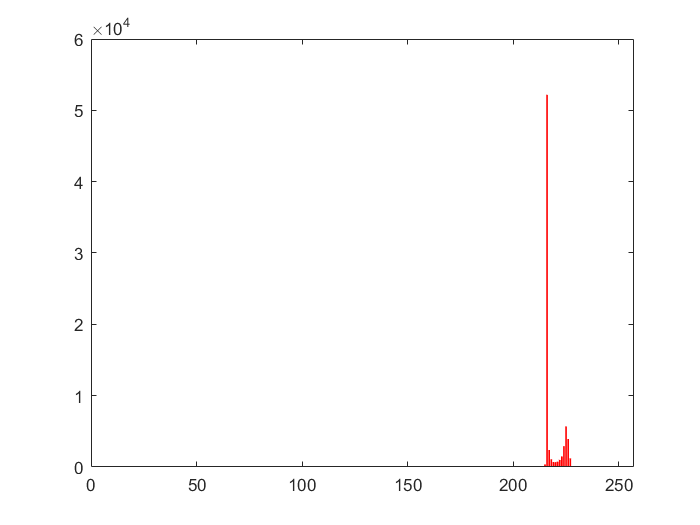

IC = imread("eight_claire.tif");
IS = imread("eight_sombre.tif");
Histo(IC);

Histo(IS);

### Q4

%Entre eight et eight_claire : 3 transformations
%1. LUT de réduction de dynamique/d'homogénisation
%2. LUT d'éclaircissement (décalage vers la droite)
%3. LUT inverse

### Q5

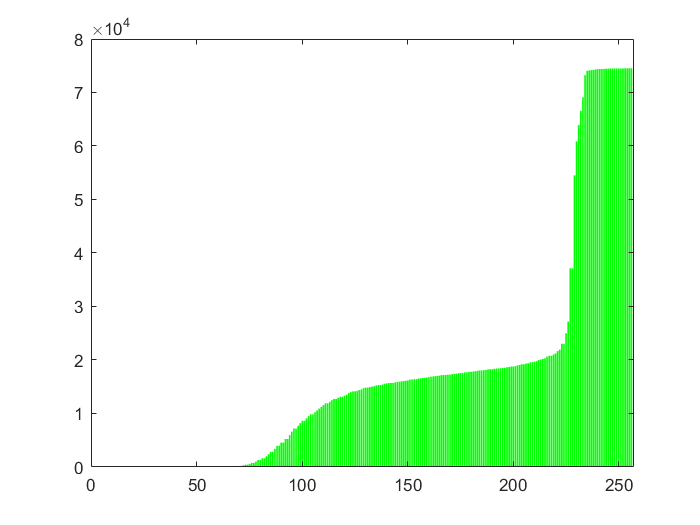

%HistoCum
HistoCum(H);

## Ex2

function myLut = recantification(N)

myLut = zeros(256:3);
clear W;
W = (256)/N;

for k = 2:N
    Tk = floor((k-1)*W);
    Rk=Tk*(N/(N-1));
    
    for j = Tk:Tk+W  
       myLut(j,1) = Rk;
       myLut(j,2) = Rk;
       myLut(j,3) = Rk;
    end
end
myLut = myLut./256;
end

## Ex3

function H = Histo(I)

H = zeros(256, 1);
[nbL, nbC] = size(I);

for i = 1:nbL
    for j = 1:nbC
        ngr = I(i,j);
        H(ngr + 1) = H(ngr + 1) + 1;
    end
end
figure
bar(H, 'r');
end

function HC = HistoCum(H)
HC = zeros(256,1);
for i = 2:256
    HC(i)=HC(i-1)+H(i);
end
figure
bar(HC, 'green');
end